# Visualization of Tristan's graph data

## Small graph data

addpath("functions")
set(0,'DefaultFigureWindowStyle','docked')

% [nodes,edges,n,emb,M,P,Cos,Sin] = build("small");
load materials\small.mat

### Visualization

The sparsity patterns for the Sin and Cos matrices.

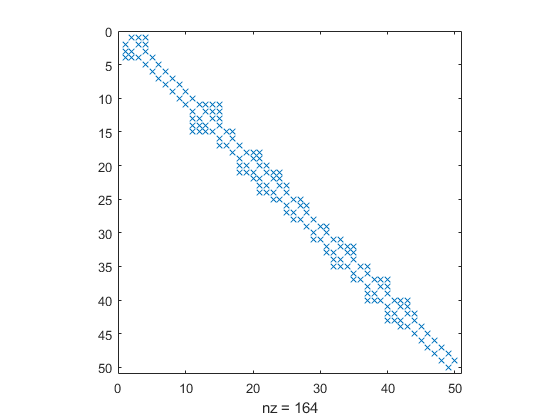

spy(Cos,'x');

The head of the M matrix. Its pattern should be falling diagonals with verticals at each iteration.

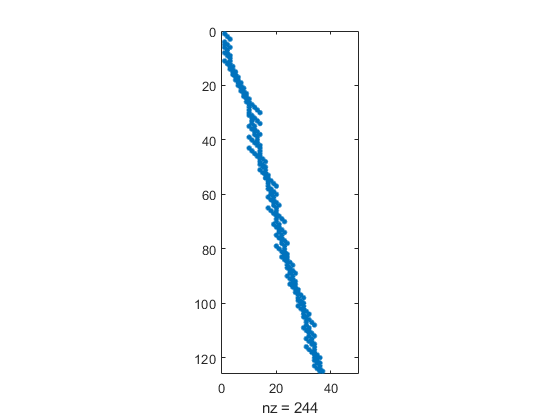

% spy(headN(M,ceil(2.5*n)));

Before we go on plotting, we created a function *(see addpoints)* to plot some points over a color gradient to keep track of the location of some specific points. Through this we get a better grasp of the embeddings' changes. *(See *[https://de.mathworks.com/help/matlab/ref/uisetcolor.html](https://de.mathworks.com/help/matlab/ref/uisetcolor.html)*)*

% uisetcolor for the colors
col1 = [1, 0, 0];
col2 = [0, 1, 0];

Plot now the actual graph that is given. **Cos** does function as the adjacency matrix here. For the real adjacency matrix get the nonzeros from Cos. If no adjacency is given we can take only the vertices without interconnections. *(See section ****large graph****)*

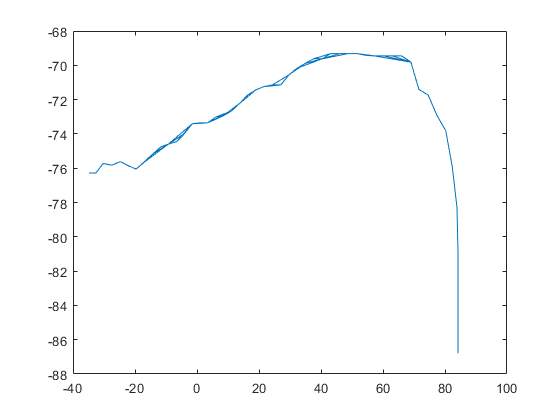

gplot(Cos,nodes(:,2:3))

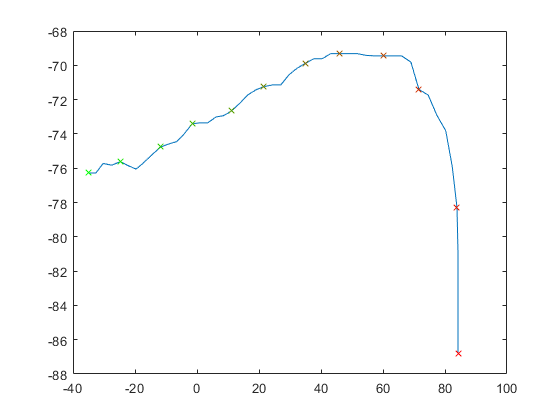

% the following two lines were rendered unnecessary due to
% plotColorgradient()
% plot(nodes(:,2),nodes(:,3),".")
% addpoints(n/4,col1,col2,nodes(:,2:3))
plotColorgradient(n/4,col1,col2,nodes(:,2:3),true,true)

Display the first embedding solution. This embedding was calculated by improper usage of **inv()**.

Update 21-01-04: emb1 no longer available

% gplot(Cos,emb1)
% plotColorgradient(n/4,col1,col2,emb1,true,true)

Display the embedding solution. This embedding was calculated by the proper way of **A\b**. Here **b** was a matrix as well. *(See ****building.mlx****)*

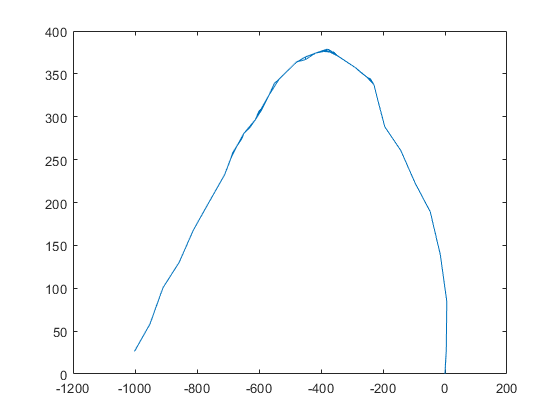

gplot(Cos,emb)

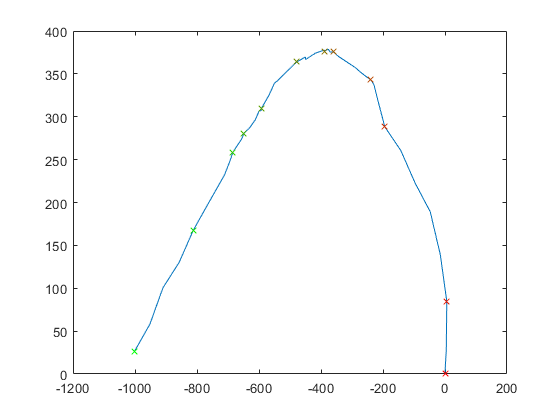

% plot(emb(:,1),emb2(:,2),".")
plotColorgradient(n/4,col1,col2,emb,true,true)

On this last graph there is visible some circular structure. This is interesting in a way that it differs the first version of the improper usage of **inv()** a lot. This might be interesting for understanding the desired solution of embeddings and worth discussing more.

### Clustering

Let us try **clustering **with **dbscan() **and **kmeans()**.

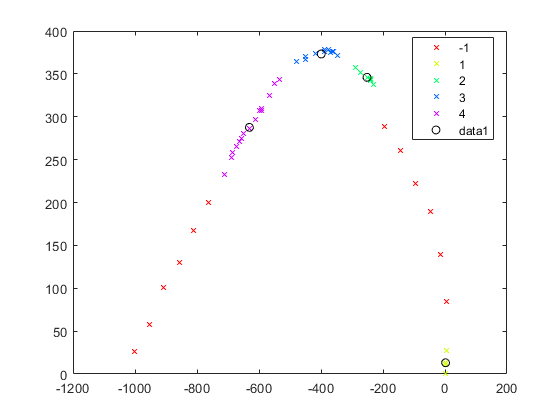

clusteredEmb = plotCluster(emb,"Type","db","Epsilon",40,"Legend","on","Minpts",3);

% clusteredEmb = plotCluster(emb);

### Aftermath

clc
clear

## Large graph data

Here we want to use the **large data set** Tristan gave us instead of the partial one above. Due to the large number of nodes and edges we cannot calculate an adjacency matrix. This would break the limit of data storage as it demands **9.4GB**. As for now we just display the nodes without interconnecting edges.

% [nodes,edges,n,emb,M,P,Cos,Sin] = build("large");
load materials\large.mat

### Visualization

The sparsity patterns for the Sin and Cos matrices.

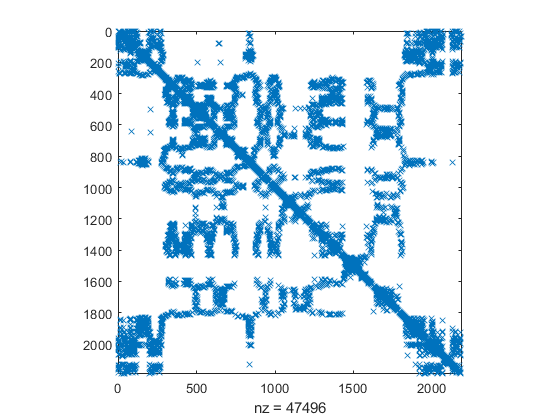

spy(Cos,'x');

The head of the M matrix. Its pattern should be falling diagonals with verticals at each iteration.

% spy(headN(M,ceil(2.5*n)));

Plot here the actual graph that is given. **Cos** does function as the adjacency matrix here. For the real adjacency matrix get the nonzeros from Cos. If no adjacency is given we can take only the vertices without interconnections. *(See section ****large graph****)*

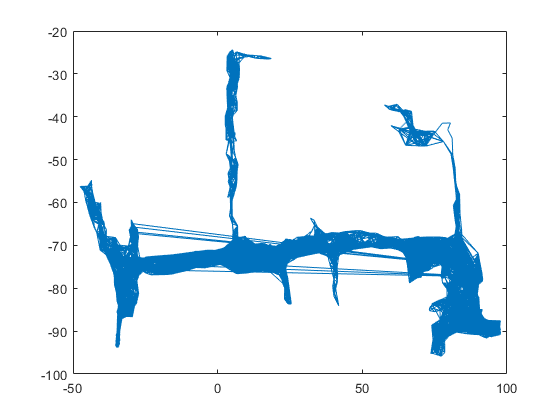

% uisetcolor for the colors
col1 = [1, 0, 0];
col2 = [0, 1, 0];

gplot(Cos,nodes(:,2:3))

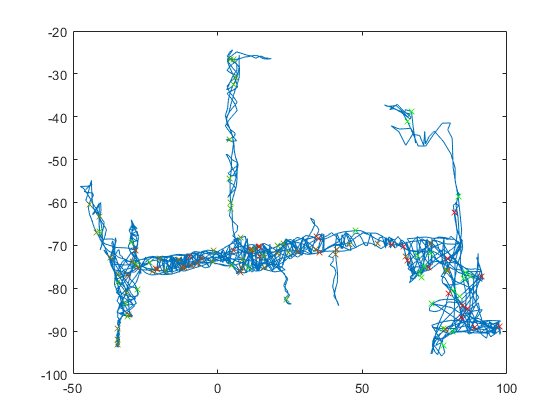

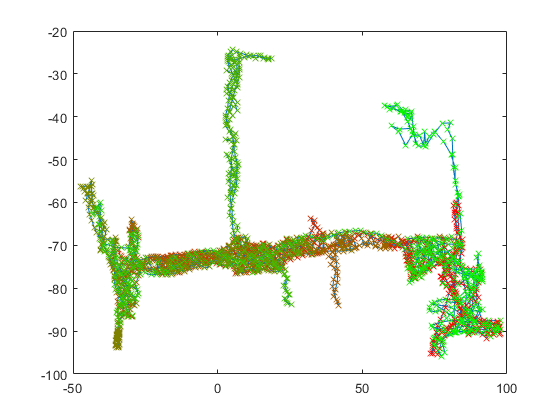

% plot(nodes(:,2),nodes(:,3),".")
plotColorgradient(n/20,col1,col2,nodes(:,2:3),true,true)

Display the first embedding solution. This embedding was calculated by improper usage of **inv()**.

Update 21-01-04: emb1 no longer available

% gplot(Cos,emb1)
% % plot(emb1(:,1),emb1(:,2),".")
% plotColorgradient(2,col1,col2,emb1,true,true)

Display the second embedding solution. This embedding was calculated by the proper way of **A\b**. Here **b** was a matrix as well. *(See ****building.mlx****)*

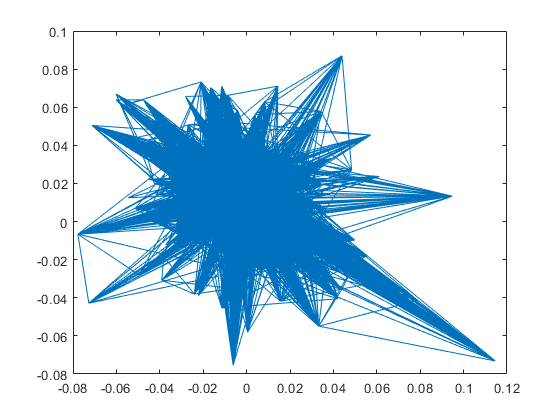

gplot(Cos,emb)

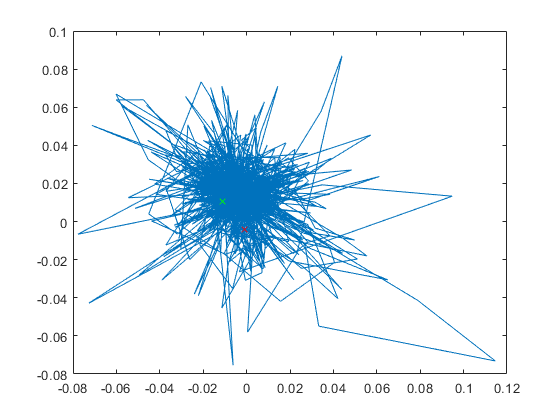

% plot(emb2(:,1),emb(:,2),".")
plotColorgradient(2,col1,col2,emb,true,true)

On this last graph there is visible some circular structure. This is interesting in a way that it differs the first version of the improper usage of **inv()** a lot. This might be interesting for understanding the desired solution of embeddings and worth discussing more.

### Clustering

Let's again cluster, this time the large graph. It is a bit more interesting than the small graph.

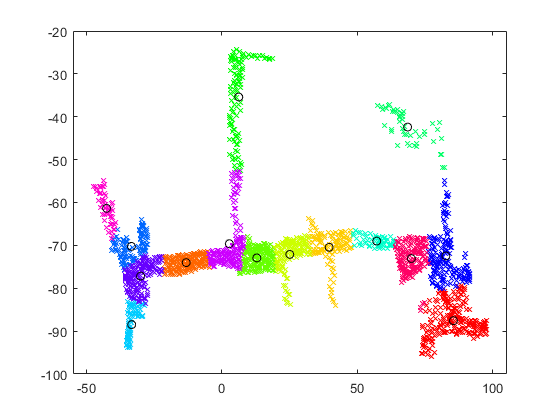

% plotCluster(nodes(:,2:3),"Epsilon",1.4,"Type","db");
plotCluster(nodes(:,2:3),"NumClusters",15);

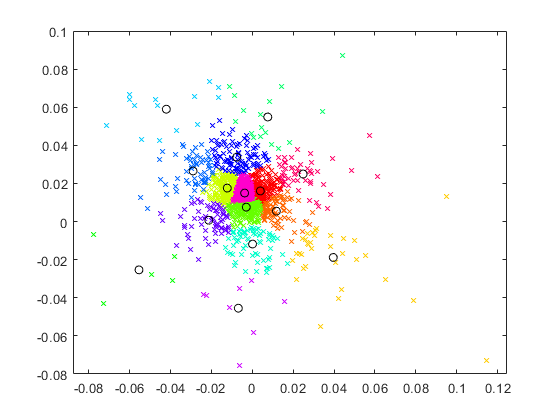

plotCluster(emb,"NumClusters",15);

### Aftermath

clc
clear

## Functions

Plots the data in a cluster either by means of 'dbscan' or 'kmeans' and adds the clustering information to the embedding and returns it.

% function clusteredEmb = plotCluster(emb,options)
%     arguments
%         emb (:,2) {mustBeNumeric}
%         options.Type (1,1) {mustBeMember(options.Type,["km","db"])} = "km"
%         
%         % "db"
%         options.Epsilon (1,1) double = 6 % threshold for neighborhood search query
%         options.Minpts (1,1) {mustBeInteger,mustBePositive} = 5 % threshold whether point is core point
%         % "km"
%         options.NumClusters (1,1) {mustBeInteger} = min(5,size(emb,1)/2)
%         
%         options.Showlabels (1,1) logical = false
%         options.Legend (1,1) {mustBeMember(options.Legend,["on","off"])} = "off"
%     end
%     
%     if issparse(emb)
%         emb = full(emb);
%     end
%     
%     if options.Type == "db"
%         idx = dbscan(emb,options.Epsilon,options.Minpts);
%     elseif options.Type == "km"
%         idx = kmeans(emb,options.NumClusters);
%     end
%     
%     numcl = size(unique(idx),1);
%     clpos = zeros(numcl,2);
%     labels = string(1:numcl);
%         
%     gscatter(emb(:,1),emb(:,2),idx,'','x',5,options.Legend)
%     hold on
%     
%     for i = 1:numcl
%         clpos(i,:) = mean(emb(idx==i,:));
%     end
%     scatter(clpos(:,1),clpos(:,2),'black')
%     
%     if options.Showlabels
%        text(clpos(:,1),clpos(:,2),labels,"FontSize",15,"HorizontalAlignment","right") 
%     end
%     
%     clusteredEmb = [emb idx];
%     
%     hold off
% end

function plotColorgradient(numPoints,col1,col2,datapoints,showLines,plotalldata)
    color_gradient = [linspace(col1(1),col2(1),numPoints)',linspace(col1(2),col2(2),numPoints)',linspace(col1(3),col2(3),numPoints)'];
    point_gradient = round(linspace(1,size(datapoints,1),numPoints));
    
    plot(datapoints(:,1),datapoints(:,2),"w")

    hold on
    
    if showLines
        if plotalldata
            plot(datapoints(:,1),datapoints(:,2),"Color",[0, 0.4470, 0.7410])  % that is the standard blue color
        else
            plot(datapoints(point_gradient,1),datapoints(point_gradient,2),"Color",[0, 0.4470, 0.7410])  % that is the standard blue color
        end
    end
    
    for i = 1:numPoints
        plot(datapoints(point_gradient(i),1),datapoints(point_gradient(i),2),"x",'Color',color_gradient(i,:))
    end
        
    hold off
end

This function is a subpart of **plotColorgradient()**.

% adds to an existing graph a number of points from the given matrix
function addpoints(numPoints,col1,col2,datapoints)
    color_gradient = [linspace(col1(1),col2(1),numPoints)',linspace(col1(2),col2(2),numPoints)',linspace(col1(3),col2(3),numPoints)'];
    point_gradient = round(linspace(1,size(datapoints,1),numPoints));
    
    hold on
    
    for i = 1:numPoints
        plot(datapoints(point_gradient(i),1),datapoints(point_gradient(i),2),"x",'Color',color_gradient(i,:))
    end
        
    hold off
end

% returns the first n rows of a given matrix
function cm = headN(mat,n)
    cm = mat(1:n,:);
end